ol
cs
ols

## Check accuracy of the forward model

Column 1000 is not modeled because 780 nm is excluded in the combs.

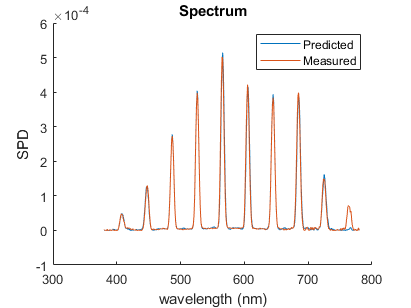

col_range  = [100:100:1000];

vec = OL490Class.VEC_multiple_peaks(col_range);

refl = ols.FWD_vec2reflC(vec);
spec = ols.FWD_vec2spdC(vec);

clf
hold on
spec.plot

ol.setColumn1024Gamma(vec)
mea = cs.measure;
mea.plot

legend('Predicted','Measured')

## Check accuracy of the inverse model

disp = NECPA271Sim

disp =   NECPA271Sim with properties:

            sc: 1
        spec_r: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 3.5551e-06 6.7073e-06 5.2896e-06 2.8394e-06 4.2835e-08 0 0 8.7784e-07 2.0290e-06 2.0501e-06 2.0390e-07 0 0 0 0 0 0 0 0 0 0 0 0 0 0 5.3891e-06 9.7155e-06 1.4314e-05 1.9349e-05 2.5347e-05 … ]
        spec_g: [0 0 0 0 0 0 0 0 0 0 0 0 2.0523e-06 3.5969e-06 3.9440e-06 3.5624e-06 2.6134e-06 1.1272e-06 0 0 0 0 0 0 1.1269e-06 2.4440e-06 2.7903e-06 2.5657e-06 1.7174e-06 0 0 0 0 0 0 0 5.8807e-07 3.8553e-06 4.4252e-06 4.3630e-06 3.9345e-06 … ]
        spec_b: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 7.3255e-07 3.1729e-06 7.2057e-06 1.1628e-05 1.6196e-05 1.9744e-05 2.1228e-05 2.3600e-05 2.7744e-05 3.5256e-05 4.7886e-05 6.3710e-05 8.2645e-05 1.0338e-04 1.2386e-04 1.4951e-04 … ]
     classpath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@NECPA271Sim'
    gamma_srgb: []
         vec_r: [1024×1 double]
    

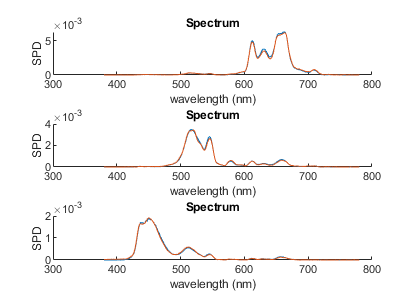

compare_RGB_primaries(ol,ols,cs,disp)

disp = HPZ24xSim

disp =   HPZ24xSim with properties:

            sc: 1
        spec_r: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 2.5701e-06 7.9307e-06 7.7670e-06 6.1644e-06 3.8131e-06 2.2553e-06 2.4673e-06 2.8140e-06 3.1157e-06 2.7609e-06 1.3275e-06 0 0 0 2.0657e-06 4.8530e-06 7.0332e-06 6.8124e-06 2.1448e-06 0 0 0 0 0 … ]
        spec_g: [1.6872e-05 2.2371e-05 2.7073e-05 3.0521e-05 3.2152e-05 2.8990e-05 2.1366e-05 1.2959e-05 5.0241e-06 1.6606e-06 3.3809e-06 6.0016e-06 8.5129e-06 7.5491e-06 2.4470e-06 0 0 0 0 0 4.4528e-06 6.9207e-06 6.0391e-06 4.4624e-06 2.6642e-06 … ]
        spec_b: [0 0 0 0 0 0 2.7105e-06 6.6530e-06 1.0032e-05 1.0610e-05 8.1888e-06 5.2439e-06 2.4440e-06 1.7566e-06 3.6596e-06 6.1397e-06 8.7775e-06 1.0703e-05 1.1502e-05 1.1768e-05 1.1484e-05 9.9314e-06 6.9855e-06 4.3556e-06 2.6863e-06 4.3033e-06 … ]
     classpath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@HPZ24xSim'
    gamma_srgb: []
         vec_r: [1024×1 double]


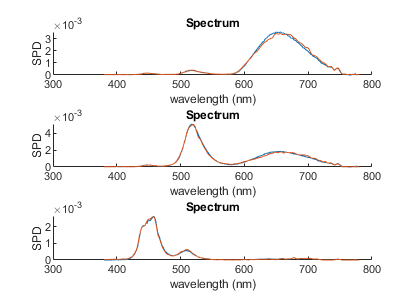

compare_RGB_primaries(ol,ols,cs,disp)

disp = RiftSim

disp =   RiftSim with properties:

      dataspec: [1024×401 double]
        ramp_r: [256×401 double]
        ramp_g: [256×401 double]
        ramp_b: [256×401 double]
         lut_x: [18×1 double]
           lut: [18×3 double]
            sc: 1
        spec_r: [2.6700e-26 2.6240e-26 2.5790e-26 3.0470e-06 9.1830e-07 1.0740e-06 2.7460e-06 2.9640e-06 8.6030e-07 1.7090e-06 2.2760e-26 2.2460e-26 6.9920e-06 2.1580e-06 4.6430e-06 2.0990e-26 2.0620e-26 2.0180e-26 1.9800e-26 1.9470e-26 1.9090e-26 … ]
        spec_g: [4.6880e-06 1.7540e-05 5.2740e-06 1.0430e-06 5.5930e-06 8.3730e-06 4.5230e-06 1.2970e-05 2.3860e-06 3.8470e-26 3.7940e-26 3.7430e-26 3.6770e-26 3.6120e-26 1.0150e-06 7.6440e-07 5.0900e-07 8.8490e-06 5.6630e-06 8.4590e-06 3.2670e-05 … ]
        spec_b: [7.1250e-06 4.6210e-08 4.2990e-26 9.8130e-06 2.9580e-06 3.4590e-06 8.8430e-06 3.9790e-26 1.1480e-07 7.7190e-06 1.2310e-05 1.1600e-05 2.4280e-05 2.9110e-05 1.2630e-05 1.19

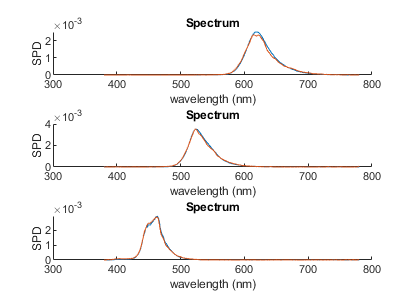

compare_RGB_primaries(ol,ols,cs,disp)

function compare_RGB_primaries (ol,ols,cs,disp)

clf

subplot(3,1,1)
hold on
v = disp.vec_r;
s_predicted = ols.FWD_vec2spdC(v);
ol.setColumn1024Gamma(v)
mea = cs.measure;
s_predicted.plot
mea.plot

subplot(3,1,2)
hold on
v = disp.vec_g;
s_predicted = ols.FWD_vec2spdC(v);
ol.setColumn1024Gamma(v)
mea = cs.measure;
s_predicted.plot
mea.plot

subplot(3,1,3)
hold on
v = disp.vec_b;
s_predicted = ols.FWD_vec2spdC(v);
ol.setColumn1024Gamma(v)
mea = cs.measure;
s_predicted.plot
mea.plot
end